# Load all data information

clear all
opts = detectImportOptions('experiment_info.csv');
ExperimentInfo = readtable('experiment_info.csv');

ID = ExperimentInfo.ID; FrameInfo = ExperimentInfo.StartFrame_EndFrame;
ReadingPath = './data/pythonPTVinfo/';
SavingPath = './data/matlabPTVinfo/';
CaliLeft = 60/782; CaliRight = 60/518; % unit is mm/pixel
index = 35;
Name = ID{index}; 
Frames = split(FrameInfo{index}, '-'); 
startF = str2num(Frames{1}); endF = str2num(Frames{2}); % calculate the start frame and end frames
Flength = (endF - startF) + 1; % Length of frames
LData = readtable([ReadingPath, Name, 'Left.csv']); 
RData = readtable([ReadingPath, Name, 'Right.csv']);
Llength = length(LData.y); Rlength = length(RData.y);
% check if Left detection has unique Particle
particleLeft = LData.particle; particleRight = RData.particle;
fprintf('Left trajectories have %d particles', length(unique(particleLeft)));

Left trajectories have 2 particles

fprintf('Right trajectories have %d particles', length(unique(particleRight)));

Right trajectories have 1 particles

% sort both data by frame number 
LData = sortrows(LData); 
RData = sortrows(RData);
FramesLeft = LData.frame; FramesRight = RData.frame;
% find the minmum startFrame both camera have
minFrame = 0;
while ~(ismember(minFrame, FramesLeft) && ismember(minFrame, FramesRight))
    minFrame = minFrame + 1;
end
fprintf('minimum start frame is frame %d', minFrame);

minimum start frame is frame 0

MaxGapLeft = max(diff(FramesLeft));
MaxGapRight = max(diff(FramesRight));
% find the maximum endFrame both camera have
maxFrame = min(FramesLeft(end),FramesRight(end));
while ~(ismember(maxFrame, FramesLeft) && ismember(maxFrame, FramesRight))
    maxFrame = maxFrame - 1;
end
fprintf('maximum end frame is frame %d', maxFrame);

maximum end frame is frame 194

MaxGapLeft = max(diff(FramesLeft));
MaxGapRight = max(diff(FramesRight));
fprintf('The maximum gap of Left Camera is %d', MaxGapLeft);

The maximum gap of Left Camera is 1

fprintf('The maximum gap of Right Camera is %d', MaxGapRight);

The maximum gap of Right Camera is 2

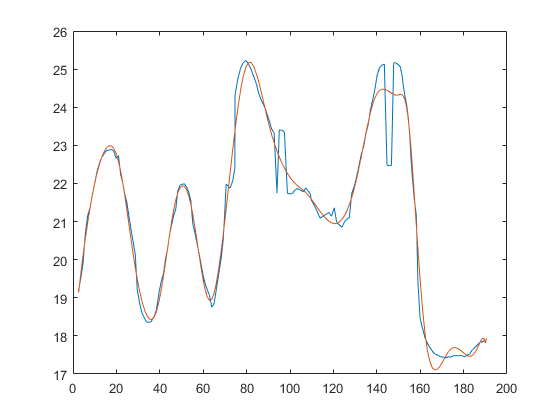

for i = minFrame:maxFrame
    LPoints{i - minFrame + 1} = [LData.x(FramesLeft == i), LData.y(FramesLeft == i)] * CaliLeft;
    RPoints{i - minFrame + 1} = [RData.x(FramesRight == i), RData.y(FramesRight == i)] * CaliRight;
end
for i = 1:length(LPoints)
    if isempty(LPoints{i})
        LPoints{i} = [nan, nan];
    end
    if isempty(RPoints{i})
        RPoints{i} = [nan, nan];
    end
end
tracksL=simpletracker(LPoints, 'MaxGapClosing', 21);
trajL=rt2traj(LPoints,tracksL,5);
trajL=trajp2traj(trajL,1/200);
tracksR=simpletracker(RPoints);
trajR=rt2traj(RPoints,tracksL,5);
trajR=trajp2traj(trajR,1/200);
figure(1)
clf
title('Left trajectory')
plot(LData.x* CaliLeft,LData.y* CaliLeft)
hold on
plot(trajL.x, trajL.y)
hold off

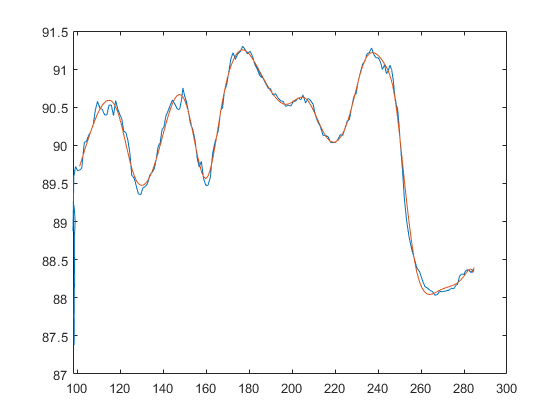

figure(2)
clf
title('Right trajector')
plot(RData.x* CaliRight,RData.y* CaliRight)
hold on
plot(trajR.x, trajR.y)
hold off

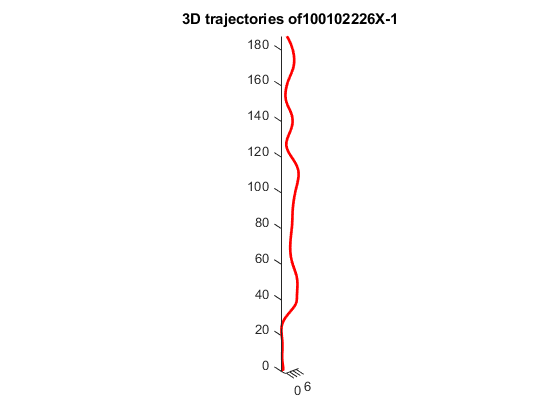

% combine Left Right Camera trajectory
w = trajL.u;
u = trajL.v;
v = trajR.v;
x = trajL.x;
y = trajL.y;
xL = (y - y(1));
zL = x(1) - x;
y = trajR.y;
yR = (y(1) - y);
traj3D = [xL,yR,zL,u,-v,-w];
figure(3)
clf
plot3(xL,yR,zL,'Color','r','LineWidth',2)
xlim([-30 30]) 
ylim([-30 30])
zlim([0 200])
title(['3D trajectories of', Name])
axis equal

save([SavingPath, Name,'.mat'],'traj3D');
SavingInfo = readtable('experiment_infoMatLab.csv');
SavingInfo.ActualStartFrame(index) = minFrame;
writetable(SavingInfo, 'experiment_infoMatLab.csv');

clear all
Name = 'P3O190_3rd';
Cali_Left = 60/760;
Cali_Right = 60/(1188-670);
LData = readtable(['Left_', Name, '.csv']);
RData = readtable(['Right_',Name, '.csv']);
L = min(length(LData.y), length(RData.y)); 
for i = 1:L
    LPoints{i} = [LData.x(i), LData.y(i)] * Cali_Left;
    RPoints{i} = [RData.x(i), RData.y(i)] * Cali_Right;
end

tracksL=simpletracker(LPoints,'Debug',true,'MaxLinkingDistance',70,'MaxGapClosing',5);
trajL=rt2traj(LPoints,tracksL,5);
trajL=trajp2traj(trajL,1/200);
tracksR=simpletracker(RPoints,'Debug',true,'MaxLinkingDistance',50,'MaxGapClosing',5);
trajR=rt2traj(RPoints,tracksR,5);
trajR=trajp2traj(trajR,1/200);



% x = trajL.x;
% y = trajL.y;
% figure(1)
% img = im2double(imread('P3O190\3rd\Left\Left0100.tif'));
% img = img/max(max(img));
% imshow(img);
% hold on;
% plot(x/Cali_Left,y/Cali_Left,'Color','r','LineWidth',2);
% hold off
% xL = (y - y(10));
% zL = x(1) - x;


w = trajL.u;
u = trajL.v;

% figure(3)
% scatter(x/Cali_Left,y/Cali_Left);

% x = trajR.x;
% y = trajR.y;
% figure(2)
% img = im2double(imread('P3O190\3rd\Right\Right0130.tif'));
% img = img/max(max(img));
% imshow(img);
% hold on;
% plot(x/Cali_Right,y/Cali_Right,'Color','r','LineWidth',2);
% hold off;
% yR = (y(1) - y);

v = trajR.v;
figure
uprime = sqrt(v.^2 + u.^2);
xplot = (0:(length(u)-1))*1/200*1000;
plot(xplot, uprime)
ylim([0,150]);
xlabel('t (ms)')
ylabel('mm/s')
saveas(gca,[Name,'Uprime.jpg'])

V = zeros(10000,1);
V(1:length(u)) = v
sp = fft(V);
L = length(V);
P2 = abs(sp/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = 200*(0:(L/2))/L;
figure
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')
saveas(gca,[Name,'VelocitySpectrum.jpg'])

% figure(4)
% scatter(x/Cali_Right,yR/Cali_Right)

% traj3D = [xL,zL,yR];
%save([Name,'.mat'],'traj3D');
figure(5)
xplot = (0:(length(u)-1))*1/200 * 1000;
speed = sqrt(u.^2 + v.^2 + w.^2);
w = -w;
plot(xplot,u);
hold on;
plot(xplot,v);
hold on;
plot(xplot,w);
hold on;
plot(xplot,speed);
hold off;
legend('u','v','w','speed', 'Location', 'eastoutside');
xlabel('t (ms)');
ylabel('mm/s');
saveas(gca,[Name,'.jpg']);

V = zeros(10000,1);
V(1:L) = trajL.x
sp = fft(V);
L = length(V);
P2 = abs(sp/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = 200*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

Plot the top view of trajectory

clear all;
Name = 'P3O190_3rd';
load([Name,'.mat']);
figure(1)
plot(traj3D(:,1),traj3D(:,3));
xlabel('X');
ylabel('Y');
axis equal
xlim([-15, 15])
ylim([-15, 15])
saveas(gca,[Name,'TopView.jpg']);
